## Matlab code for generateing main figs (Fig3) in the following paper:

Shuxiong Wang, et al., **single cell trascriptomics of human epidermis reveals basal stem cell transition states**, *nature communications (to appear)*, 2020

- All the results are generated by applying SoptSC to the single-cell rna-seq data, for detailed useage of SoptSC, please refer to

- [https://github.com/WangShuxiong/SoptSC](https://github.com/WangShuxiong/SoptSC)

- Some figures are generated using custermized code below

% Add tools into matlab path
addpath('Data');
addpath('Cell_Cell_Communication');

% Set the folder to save all figures
folder = 'Results\Fig3';
folder1 = 'Results/Fig3';

#### Step 1 (Required)

Load data

%% Step 1: load data
load Data/data_fig3.mat;

#### Step 2 (Optional) -- skip this step to save time

We have done this step and saved the results in **data_fig3.mat**

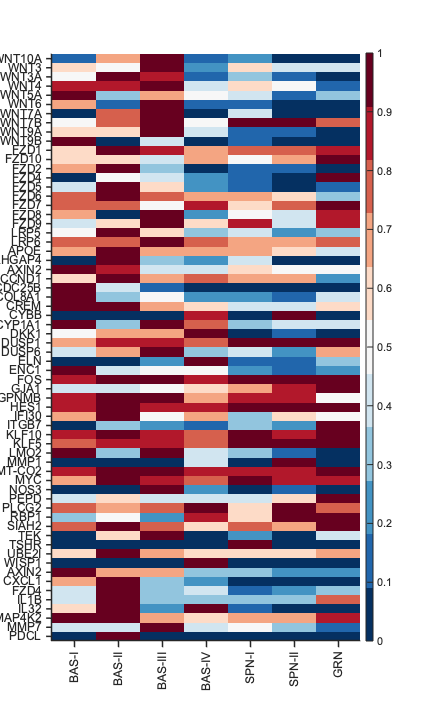

%% Step 2-1: find l-r pair that in the gene list; find target that in the list
[Lig,Rec] = ligand_receptor_in_list(allgenes,Lig,Rec);
target_up = intersect(allgenes,target_up);

target_down = intersect(allgenes,target_down);

#### Skip step 2-2

%% Step 2-2: Run SoptSC to infer cell-cell (cluster-cluster) interation probability matrix
[P_cell_each_lr,P_cell_agg,P_cluster_each_lr,P_cluster_agg] = LR_Interaction(data,allgenes,cluster_lab,Lig,Rec,target_up,target_down);

#### Skip step 2-3

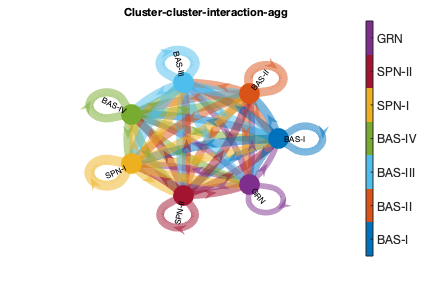

%% Step 2-3: Clustering L-R pairs
text_on = 1; % 0: not l-r names; 1: l-r names on;

NC_LR = 7;   % Number of clusters for l-r pairs
figname1 = 'Cluster_LR_Wnt';
cluster_lab_lr = cluster_LR(P_cluster_each_lr,NC_LR,Lig,Rec,figname1,folder,text_on);

#### Step 3: Generating all mian figures (Fig3) in the paper

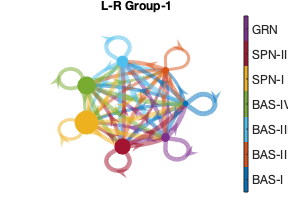

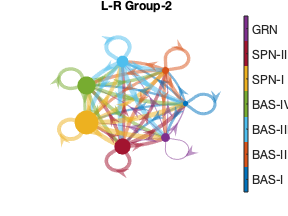

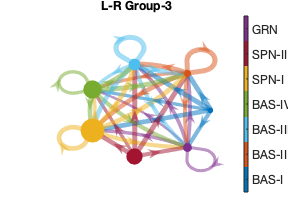

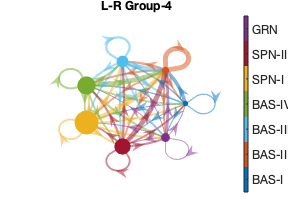

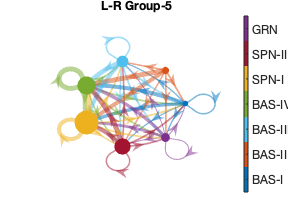

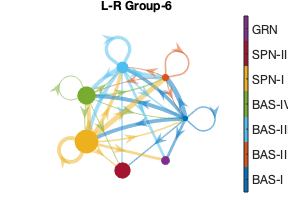

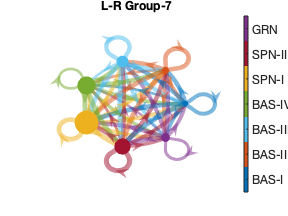

%% plot average expression of selected genes in each cluster
figname1 = 'LR_mean';
gene_selected = [unique(Lig);unique(Rec);unique(target_up);unique(target_down)];
reorder = 1:length(lgd);
plot_mean_matrix(data,gene_selected,allgenes,lgd,cluster_lab,reorder,figname1,folder);

## Fig3B

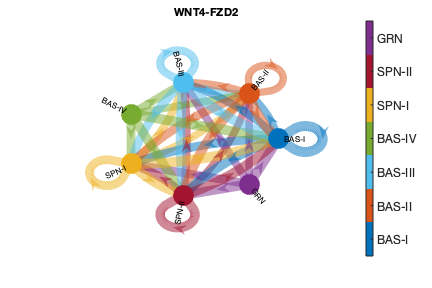

% dot size
P_dot_size = dot_size_LR(data,Lig,Rec,allgenes,cluster_lab);

%% plot dot-heatmap at cluster-level for all lig-rec pairs
figname = 'Dot_heatmap';
cluster_order_lr = 1:NC_LR;

reorder = 1:length(lgd);
plot_dot_heatmap(P_cluster_each_lr,P_dot_size,Lig,Rec,lgd,cluster_color,color_lr_all,reorder,cluster_lab_lr,cluster_order_lr,folder,figname);

## Fig3C

%% plot aggegration of cluster-cluster interations (aggegration of all l-r pair)
figname = 'Cluster-cluster-interaction-agg';
threshold = 0.3;
plot_sig_network(P_cluster_agg,cluster_lab,threshold,lgd,folder,figname,cluster_color);

## Fig3D

%% plot cluster-cluster interactions based on the groups of ligand-receptor pairs
threshold = 0.1;
figname = 'Signaling_cluster';
cluster_order_lr = 1:NC_LR;
plot_sig_network_group_lr(P_cluster_each_lr,lgd,threshold,cluster_lab,cluster_lab_lr,cluster_order_lr,cluster_color,figname,folder);

%% plot cluster-cluster interations for a specific ligand-receptor pair
lr_number = 6; % plot the 3rd l-r pair

figname = [Lig{lr_number} '-' Rec{lr_number}];
threshold = 0.3;
plot_sig_network(P_cluster_each_lr{lr_number},cluster_lab,threshold,lgd,folder,figname,cluster_color);